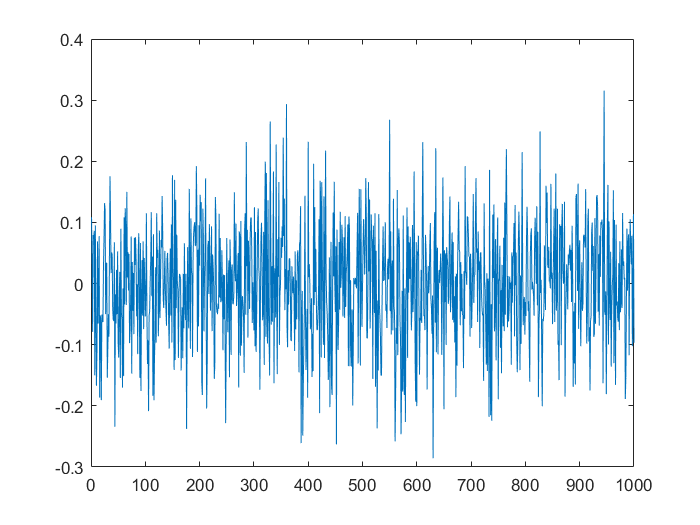

clear;
samples = 1000;
%r = wgn(4,samples,-30);
r_cov = 0.1;
r_mean = 0;
r = r_mean + r_cov*randn(4,samples);
figure();
plot(r(1,:));

S_p = zeros(4,1);
S_n = zeros(4,1);
zero = zeros(4,1);
for i = 1:samples
    r_a = r(:,i);
    for j = 1:4
        S_p(j) = max(0,S_p(j) + r_a(j));
        S_n(j) = min(0,S_n(j) + r_a(j));
    end
    %S_p = max([zero S_p + r_a]) %If residue is +ve, it is added to S_p, if it was -ve, then S_p drops to a min 0
    %S_n = min([zero S_n + r_a]) %If residue is -ve, it is added to S_n, making it more -ve. If it is +ve, S_n increases, moving towards 0 
    S_p_arr(:,i) = S_p;
    S_n_arr(:,i) = S_n;
end

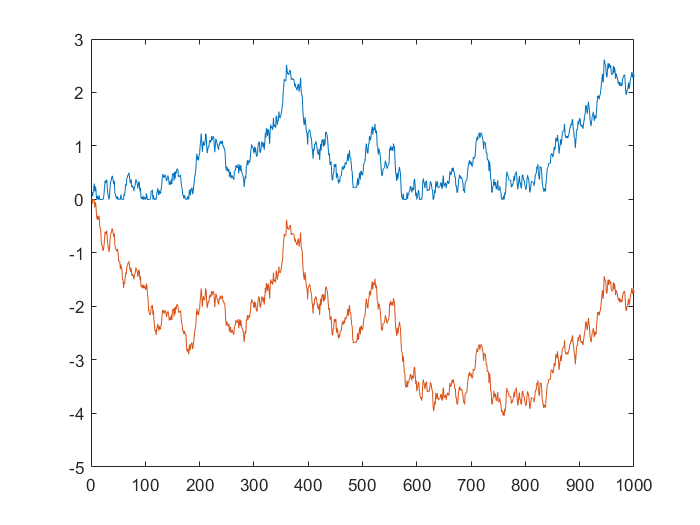

index = 1;
figure();
plot(S_p_arr(index,:));
hold on;
plot(S_n_arr(index,:));
hold off;